# audioFeatureExtractorを用いた特徴抽出と転移学習YAMNetによる異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

[https://jp.mathworks.com/help/audio/ref/yamnet.html](https://jp.mathworks.com/help/audio/ref/yamnet.html)

audioFeatureExtractorを用いた特徴抽出は以下のページをご参照ください。

アプリベース

[https://jp.mathworks.com/help/audio/ref/extractaudiofeatures.html](https://jp.mathworks.com/help/audio/ref/extractaudiofeatures.html)

コマンドベース

[https://jp.mathworks.com/help/audio/ref/audiofeatureextractor.html](https://jp.mathworks.com/help/audio/ref/audiofeatureextractor.html)

YAMNetを用いた転移学習は以下のページをご参照ください。

[https://jp.mathworks.com/help/audio/ref/yamnet.html](https://jp.mathworks.com/help/audio/ref/yamnet.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Deep Learning Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
downloadFolder = fullfile(tempdir,'aircompressordataset');
datasetLocation = tempdir;

if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
    loc = websave(downloadFolder,url);
    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
end

ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads); %* データのシャッフル
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

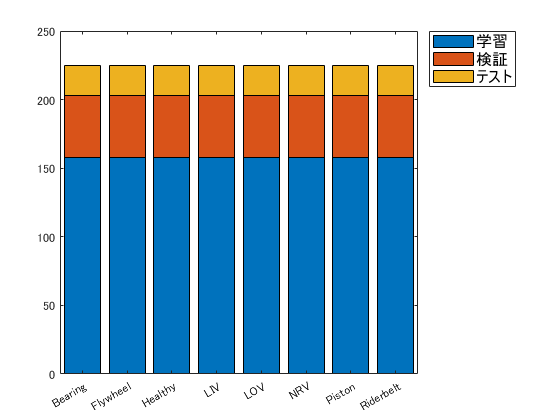

uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## 可視化

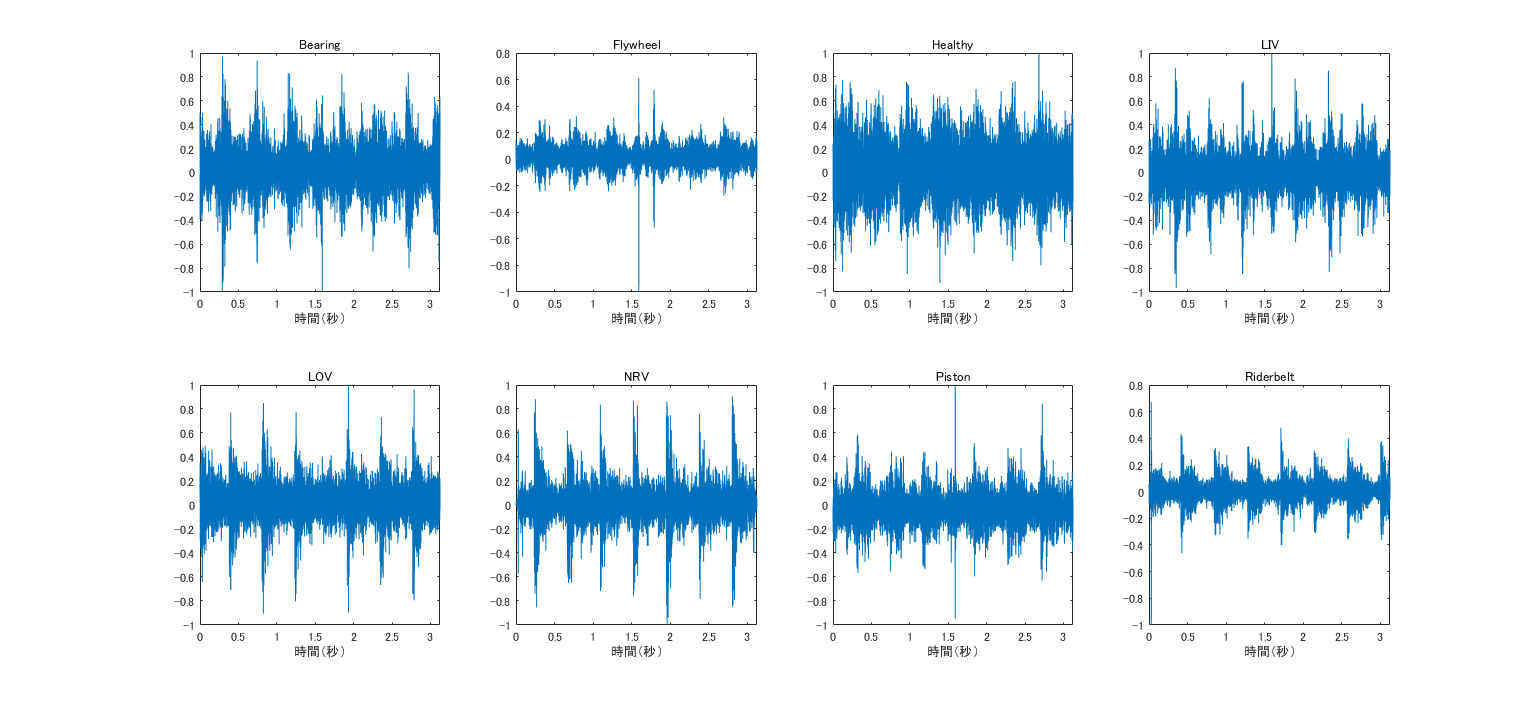

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## 特徴抽出：バーク周波数スペクトラム

コマンドライン、または、タスクからExtract Audio Featuresを活用

afe = audioFeatureExtractor('SampleRate',fs, ...
    'Window',hann(0.025*fs,'periodic'), ...
    'OverlapLength',round(0.015*fs), ...
    'barkSpectrum',true);
setExtractorParams(afe,'barkSpectrum','NumBands',64); %* default NumBands: 32

## 学習用

numSpectrumsPerSpectrogram = 96;
numSpectrumsOverlapBetweenSpectrograms = 48;
numSpectrumsHopBetweenSpectrograms = numSpectrumsPerSpectrogram - numSpectrumsOverlapBetweenSpectrograms;

emptyLabelVector = adsTrain.Labels;
emptyLabelVector(:) = [];

trainFeatures = [];
trainLabels = emptyLabelVector;
reset(adsTrain);
tic
while hasdata(adsTrain)
    [audioIn,fileInfo] = read(adsTrain);
    features = extract(afe,audioIn);
    features = log10(features + single(0.001));
    [numSpectrums,numBands] = size(features);
    numSpectrograms = floor((numSpectrums - numSpectrumsPerSpectrogram)/numSpectrumsHopBetweenSpectrograms) + 1;
    for hop = 1:numSpectrograms
        range = 1 + numSpectrumsHopBetweenSpectrograms*(hop-1):numSpectrumsHopBetweenSpectrograms*(hop-1) + numSpectrumsPerSpectrogram;
        trainFeatures = cat(4,trainFeatures,features(range,:));
        trainLabels = cat(1,trainLabels,fileInfo.Label);
    end
end
toc

経過時間は 160.069519 秒です。


## 検証用

validationFeatures = [];
validationLabels = emptyLabelVector;
tic
while hasdata(adsValidation)
    [audioIn,fileInfo] = read(adsValidation);
    features = extract(afe,audioIn);
    features = log10(features + single(0.001));
    [numSpectrums,numBands] = size(features);
    numSpectrograms = floor((numSpectrums - numSpectrumsPerSpectrogram)/numSpectrumsHopBetweenSpectrograms) + 1;
    for hop = 1:numSpectrograms
        range = 1 + numSpectrumsHopBetweenSpectrograms*(hop-1):numSpectrumsHopBetweenSpectrograms*(hop-1) + numSpectrumsPerSpectrogram;
        validationFeatures = cat(4,validationFeatures,features(range,:));
        validationLabels = cat(1,validationLabels,fileInfo.Label);
    end
end
toc

経過時間は 14.947692 秒です。


## テスト用

testFeatures = [];
testLabels = emptyLabelVector;
tic
while hasdata(adsTest)
    [audioIn,fileInfo] = read(adsTest);
    features = extract(afe,audioIn);
    features = log10(features + single(0.001));
    [numSpectrums,numBands] = size(features);
    numSpectrograms = floor((numSpectrums - numSpectrumsPerSpectrogram)/numSpectrumsHopBetweenSpectrograms) + 1;
    for hop = 1:numSpectrograms
        range = 1 + numSpectrumsHopBetweenSpectrograms*(hop-1):numSpectrumsHopBetweenSpectrograms*(hop-1) + numSpectrumsPerSpectrogram;
        testFeatures = cat(4,testFeatures,features(range,:));
        testLabels = cat(1,testLabels,fileInfo.Label);
    end
end
toc

経過時間は 4.565292 秒です。


## 学習済みネットワーク YAMNet の読み込み

downloadFolder = fullfile(tempdir,'YAMNetDownload');
loc = websave(downloadFolder,'https://ssd.mathworks.com/supportfiles/audio/yamnet.zip');
YAMNetLocation = tempdir;
unzip(loc,YAMNetLocation)
addpath(fullfile(YAMNetLocation,'yamnet'))

## 出力層の変更

uniqueLabels = unique(adsTrain.Labels);
numLabels = numel(uniqueLabels);

net = yamnet;

lgraph = layerGraph(net.Layers);

newDenseLayer = fullyConnectedLayer(numLabels,"Name","dense");
lgraph = replaceLayer(lgraph,"dense",newDenseLayer); %* 全結合層を8クラスに付け替え

newClassificationLayer = classificationLayer("Name","Sounds","Classes",uniqueLabels);
lgraph = replaceLayer(lgraph,"Sound",newClassificationLayer); %* 出力層も再定義

## 学習のオプション

miniBatchSize = 128;
validationFrequency = floor(numel(trainLabels)/miniBatchSize);

options = trainingOptions('adam', ...
    'InitialLearnRate',3e-4, ...
    'MaxEpochs',2, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{single(validationFeatures),validationLabels}, ...
    'ValidationFrequency',validationFrequency);

## 学習の開始

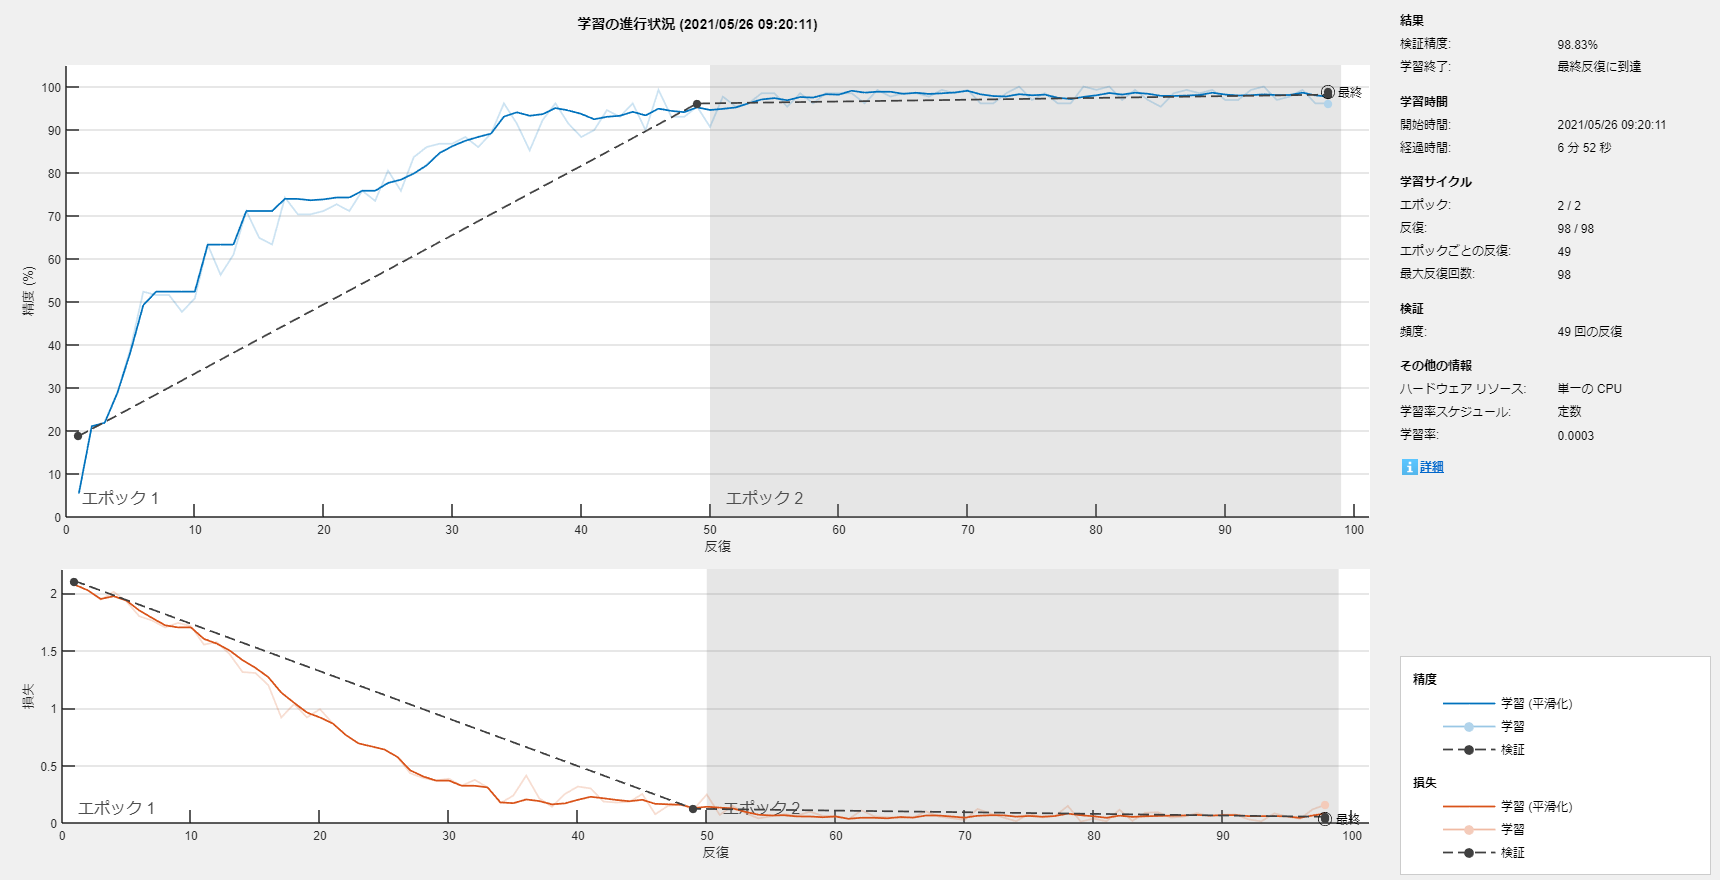

trainedNet = trainNetwork(single(trainFeatures),trainLabels,lgraph,options);

## テスト：精度検証

summary(testLabels)

     Bearing        110 
     Flywheel       110 
     Healthy        110 
     LIV            110 
     LOV            110 
     NRV            110 
     Piston         110 
     Riderbelt      110 


predLabels = classify(trainedNet,single(testFeatures));
accuracy = 100*sum(predLabels == testLabels) / numel(testLabels) % 精度（%）

accuracy = 98.7500

## 混同行列

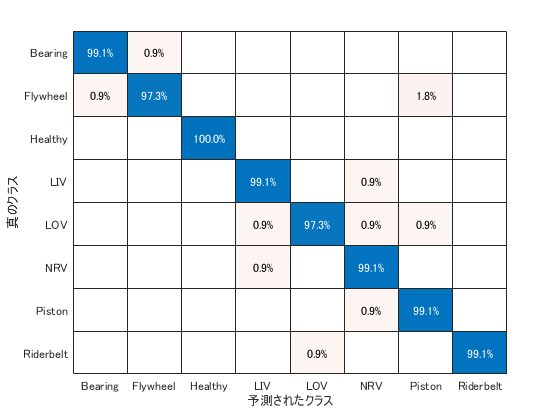

figure; clf;
confusionchart(testLabels, predLabels, "Normalization","row-normalized");

## 精度の可視化

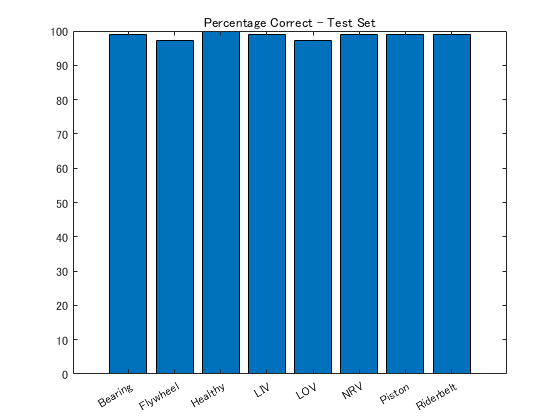

cm = confusionmat(testLabels, predLabels);
genreAccuracy = diag(cm)./countcats(testLabels)*100;
figure; clf;
bar(genreAccuracy)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct - Test Set');

*Copyright 2021 The MathWorks, Inc.*